**1) Let's assume y = 0.5e^(0.1x) + 2        Let's plot this function from x = 0 to 40**

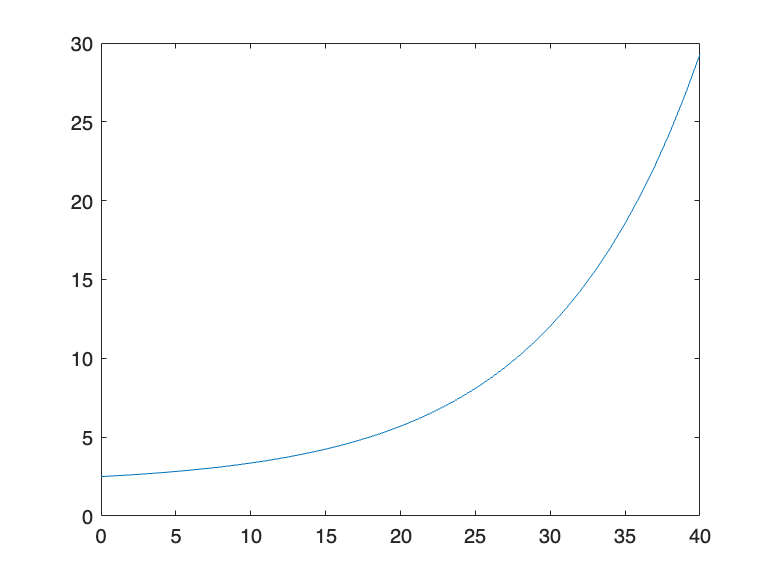

xx = 0:1:40;
yy = 0.5 * exp(0.1 * xx) + 2;
plot(xx, yy, '-')

 **2) Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use linear interpolation to predict the unknown function**

x = linspace(0, 40, 2)';
y = 0.5 * exp(0.1 * x) + 2;

p1 = polyfit(x, y, 1)

p1 =     0.6700    2.5000


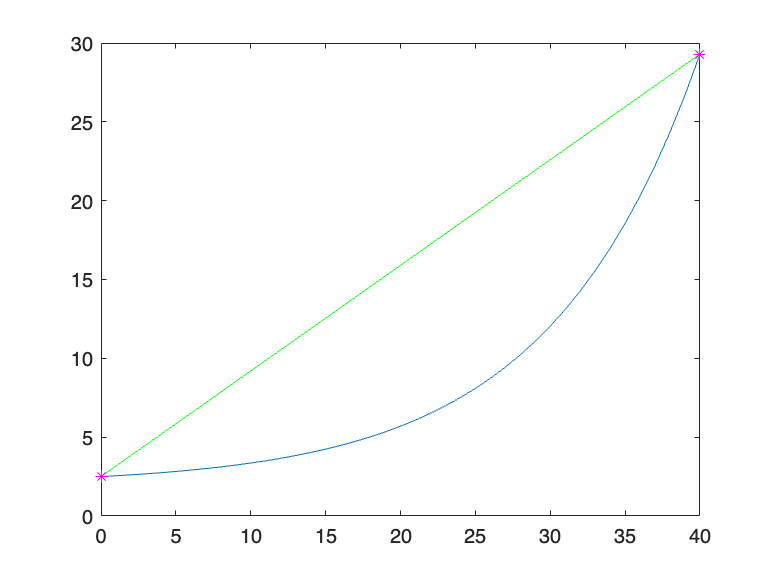


xx = 0:1:40;
yy1 = polyval(p1, xx);

plot(xx, yy, '-')
hold on
plot(xx, yy1, 'g-',x , y, 'm*')
hold off

**3) Now assume that we only know 3 points with equal interval between 0 and 40, then we can use quadratic interpolation to predict the unknown function**

x = linspace(0, 40, 3)';
y = 0.5 * exp(0.1 * x) + 2;

p2 = polyfit(x, y, 2)

p2 =     0.0255   -0.3505    2.5000


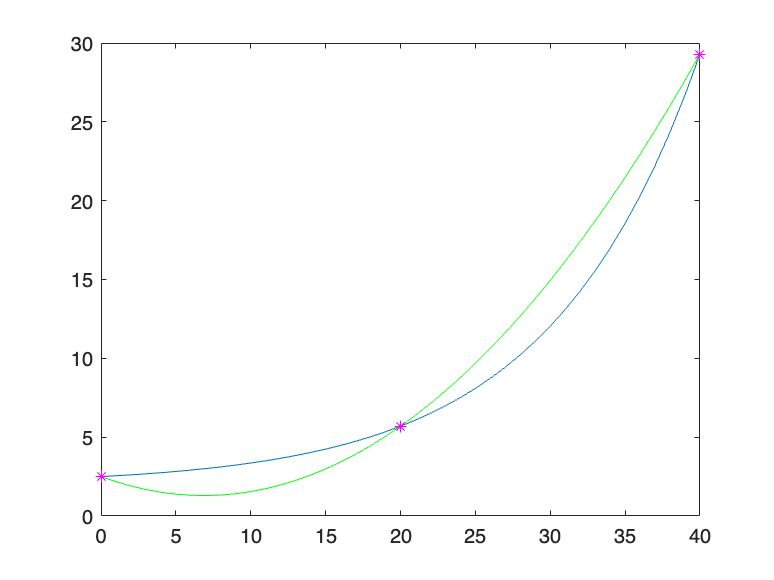


xx = 0:1:40;
yy2 = polyval(p2, xx);

plot(xx, yy, '-')
hold on
plot(xx, yy2, 'g-',x , y, 'm*')
hold off

**4) Now assume that we only know 4 points with equal interval between 0 and 40, then we can use cubic interpolation to predict the unknown function**

x = linspace(0, 40, 4)';
y = 0.5 * exp(0.1 * x) + 2;

p3 = polyfit(x, y, 3)

p3 =     0.0008   -0.0197    0.2310    2.5000


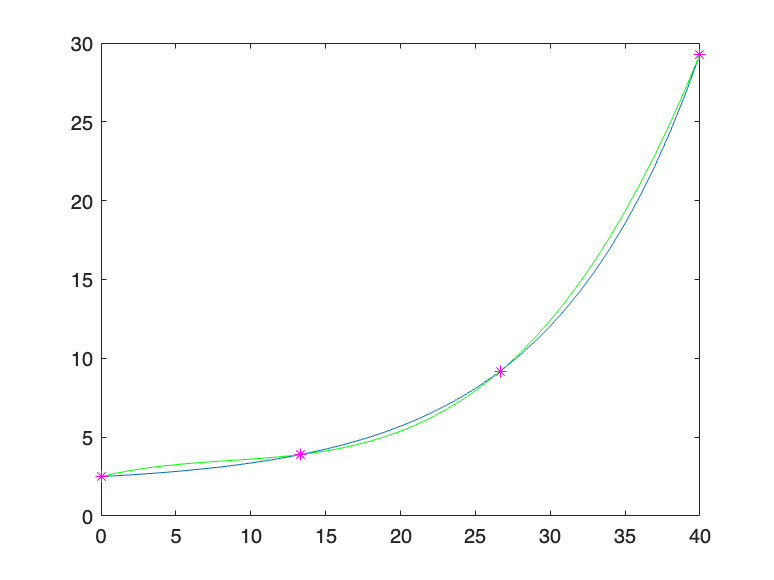


xx = 0:1:40;
yy3 = polyval(p3, xx);

plot(xx, yy, '-')
hold on
plot(xx, yy3, 'g-',x , y, 'm*')
hold off